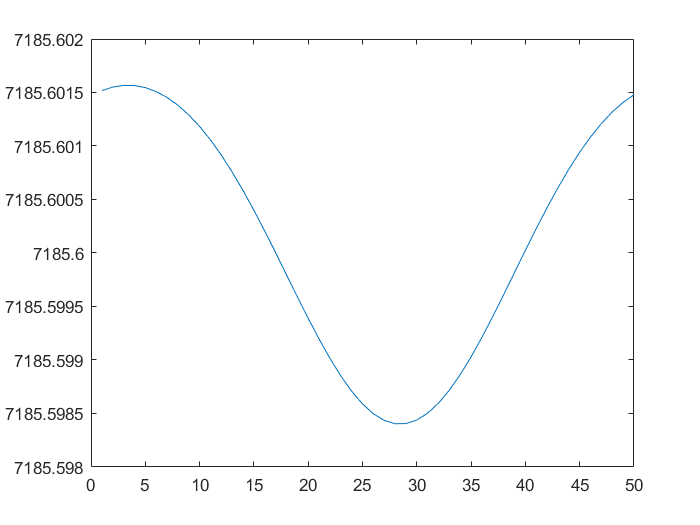

% distance from leading satellite to tracking satellite, comgpsrangeresidualsimuantphasecorrputgpsrangeresidualsimuantphasecorred from the
% simulated trajectory data
% diff_c_d = inertialtrajectory20190101D0411 - inertialtrajectory20190101C0411;
% distance_from_simu = sqrt(diag(diff_c_d * diff_c_d'));


% deprive simulated trajectory and light-time correction from biased range
% gpsrangeresidualsimuantphasecorr = TH0401KBR1B20190101X0820210801000000(:, 1) - TH0401KBR1B20190101X0820210801000000(:, 2) - distance_from_simu;
gpsrangeresidualsimuantphasecorr_5times = repmat(gpsrangeresidualsimuantphasecorr(1: 200), 5, 1);

figure
plot(filter_pdfree(Num9, gpsrangeresidualsimuantphasecorr(1: 200))); hold on;

eqa86400_1_2_matched = match_filter(Num9, eqa86400(1: 200, :));
eqb_filtered = filter_pdfree(Num9, gpsrangeresidualsimuantphasecorr(1: 200));
gpsrangeresidualsimuantphasecorr_1_2_filtered = (eqb_filtered - mean(eqb_filtered - match_filter(Num9, antphasecorrsimu86400(1: 200))));
gpsrangeresidualsimuantphasecorr_1_2_filtered_prime = eqa86400_1_2_matched(:, [4, 5, 6, 2]) * [-1.5201; -0.0234; -0.0318; 0.0322] - gpsrangeresidualsimuantphasecorr_1_2_filtered;
% bbb = lsqr(diff(eqa86400_1_2_matched, 1, 1), diff(gpsrangeresidualsimuantphasecorr_1_2_filtered));
aaaa = solver_freq(filter_pdfree(Num9, eqa86400(1: 200, :)), filter_pdfree(Num9, gpsrangeresidualsimuantphasecorr(1: 200)), [1, 3], 0.2, [0.004, 0.008])

ans =           109.260296320274


lsqr converged at iteration 2 to a solution with relative residual 1.6e-11.


aaaa =           1.52707271302152
        0.0387326905727085


cccc = solver_freq(diff(eqa86400(1: 101, :), 1, 1), diff(gpsrangeresidualsimuantphasecorr(1: 101)), [1, 3], 0.2, [0.004, 0.008])

ans =           256.448683449615


lsqr converged at iteration 2 to a solution with relative residual 1.5e-12.


cccc =            1.5981934010584
        0.0381160684469198


diff(eqa86400(1: 201, :), 1, 1) \ diff(gpsrangeresidualsimuantphasecorr(1: 201))

ans =           1.44115216909496
        0.0215664423815022
        0.0408303714488697
         -4367.90122902043
          1.03493119369687
         0.587757075407764


b = [1.50; 0.04];
acos(sum(cccc .* b) / norm(b) / norm(cccc))

ans =        0.00281539687199947


bbbb = lsqr(eqa86400_1_2_matched(:, [1, 3]), gpsrangeresidualsimuantphasecorr_1_2_filtered_prime, 1e-9, 1e8)

lsqr converged at iteration 3 to a solution with relative residual 4.9e-06.


bbbb =          -1.46989305661516
       -0.0403534625897779


b = [-1.50; -0.04];
acos(sum(bbbb .* b) / norm(b) / norm(bbbb))

ans =       0.000786090024738708


error

Error using error
Not enough input arguments.

figure
plot(1: 5: 250, match_filter(Num, antphasecorrsimu86400(1: 200))); hold on
plot(1: 5: 250, filter_pdfree(Num9, gpsrangeresidualsimuantphasecorr(1: 200)) - mean(filter_pdfree(Num9, gpsrangeresidualsimuantphasecorr(1: 200)) - match_filter(Num, antphasecorrsimu86400(1: 200))))
grid on;
set(gcf, 'Units', 'centimeters', 'Position', [10 10 70 60]);
xlabel('Time [s]', 'fontsize', 20);
ylabel('Amplitude [m]', 'fontsize', 20);
set(gca, 'FontSize', 20, 'linewidth', 1.1)
legend('simulated', 'filtered')
% data wrap
n_times = 10;
gpsrangeresidualsimuantphasecorr_filtered_ntimes = repmat(filter_pdfree(Num, gpsrangeresidualsimuantphasecorr(1: 200)) - mean(filter_pdfree(Num, gpsrangeresidualsimuantphasecorr(1: 200)) - match_filter(Num, antphasecorrsimu86400(1: 200))), n_times, 1);
ant_ntimes = repmat(match_filter(Num, antphasecorrsimu86400(1: 200)), n_times, 1);
eqa86400_ntimes = repmat(match_filter(Num, eqa86400(1: 200, :)), n_times, 1);
start_epoch = zeros(n_times - 1, 1);
for i = 1: n_times - 1
    start_epoch(i) = 50 * i + 1;
end
gpsrangeresidualsimuantphasecorr_wrap_temp = gpsrangeresidualsimuantphasecorr_filtered_ntimes;
gpsrangeresidualsimuantphasecorr_wrap= gpsrangeresidualsimuantphasecorr_filtered_ntimes;
for i = 1: length(start_epoch)
    temp = interp1(1: start_epoch(i) - 1, gpsrangeresidualsimuantphasecorr_wrap_temp(1: start_epoch(i) - 1), start_epoch(i), 'linear', 'extrap');
    gpsrangeresidualsimuantphasecorr_wrap(start_epoch(i): end) = gpsrangeresidualsimuantphasecorr_wrap(start_epoch(i): end) - gpsrangeresidualsimuantphasecorr_wrap(start_epoch(i)) + temp;
    gpsrangeresidualsimuantphasecorr_wrap_temp = gpsrangeresidualsimuantphasecorr_wrap;
end
figure
plot(gpsrangeresidualsimuantphasecorr_wrap)
set(gcf, 'Units', 'centimeters', 'Position', [10 10 70 60]);
xlabel('Time [s]', 'fontsize', 20);
ylabel('Amplitude [m]', 'fontsize', 20);
set(gca, 'FontSize', 20, 'linewidth', 1.1)
figure
plot(filter_pdfree(Num1, gpsrangeresidualsimuantphasecorr_wrap) - mean(filter_pdfree(Num1, gpsrangeresidualsimuantphasecorr_wrap) - match_filter(Num1, ant_ntimes))); hold on;
plot(match_filter(Num1, ant_ntimes));
set(gcf, 'Units', 'centimeters', 'Position', [10 10 70 60]);
xlabel('Time [s]', 'fontsize', 20);
ylabel('Amplitude [m]', 'fontsize', 20);
set(gca, 'FontSize', 20, 'linewidth', 1.1)
legend("filtered", "simulated")

eqa86400_1_2_matched = match_filter(Num1, eqa86400_ntimes);
gpsrangeresidualsimuantphasecorr_1_2_filtered = (filter_pdfree(Num1, gpsrangeresidualsimuantphasecorr_wrap) - mean(filter_pdfree(Num1, gpsrangeresidualsimuantphasecorr_wrap) - match_filter(Num1, ant_ntimes)));
gpsrangeresidualsimuantphasecorr_1_2_filtered_prime = eqa86400_1_2_matched(:, [4, 5, 6, 2]) * [-1.4901; -0.0204; -0.0308; 0.0302] - gpsrangeresidualsimuantphasecorr_1_2_filtered;
bbb = lsqr(diff(eqa86400_1_2_matched, 1, 1), diff(gpsrangeresidualsimuantphasecorr_1_2_filtered))
cccc = solver_freq(eqa86400_1_2_matched, gpsrangeresidualsimuantphasecorr_1_2_filtered, [1, 3], 0.2, [0.004, 0.008])
bbbb = lsqr(eqa86400_1_2_matched(:, [1, 3]), gpsrangeresidualsimuantphasecorr_1_2_filtered_prime, 1e-9, 1e8)
% lsqr(eqa86400_1_2_matched, gpsrangeresidualsimuantphasecorr_1_2_filtered, 1e-15, 1e8)
b = [-1.50; -0.04];
b_error = bbbb(1: 2) - b;

acos(sum(bbbb .* b) / norm(b) / norm(bbbb))